## **Covid Detection Transfer Learning (resnet18)**

## Load Data 

% Uncomment lines 3-5 AND comment lines 8-28 if you want to test with the 
% data splits provided by the UCSD data github.
% imdsTest = imageDatastore(fullfile('ucsd_Data','test'),'IncludeSubfolders',true,'LabelSource','foldernames');
% imdsTrain = imageDatastore(fullfile('ucsd_Data','train'),'IncludeSubfolders',true,'LabelSource','foldernames');
% imdsValidation = imageDatastore(fullfile('ucsd_Data','validation'),'IncludeSubfolders',true,'LabelSource','foldernames');

% Uncomment lines 8 - 28 if you want to test your own data splits.
% imds = imageDatastore(fullfile('images_and_split',{'CT_COVID','CT_NonCOVID'}),'IncludeSubfolders', ...
%      true,'LabelSource','foldernames');
% 
% % Test different splits of training, validation, and testing.
% % Make sure percentages add up to 1.

% % Training Split
% percent_train = 0.75;
% % Validation Split
% percent_val = 0.125;
% % Testing Split
% percent_test = 1 - (percent_train + percent_val);
% 
% % Check for invalid percentage.
% if(percent_test < 0 || percent_val < 0 || percent_test < 0 || ...
%    percent_test > 1 || percent_val > 1 || percent_test > 1)
%     fprintf("Invalid percentages.")
%     return;
% end
% 
% [imdsTrain,imdsValidation,imdsTest] = splitEachLabel(imds,percent_train,percent_val,percent_test,'randomize');

## Load Pretrained Network

net = resnet18;

Use `analyzeNetwork` to display an interactive visualization of the network architecture and detailed information about the network layers.

analyzeNetwork(net);

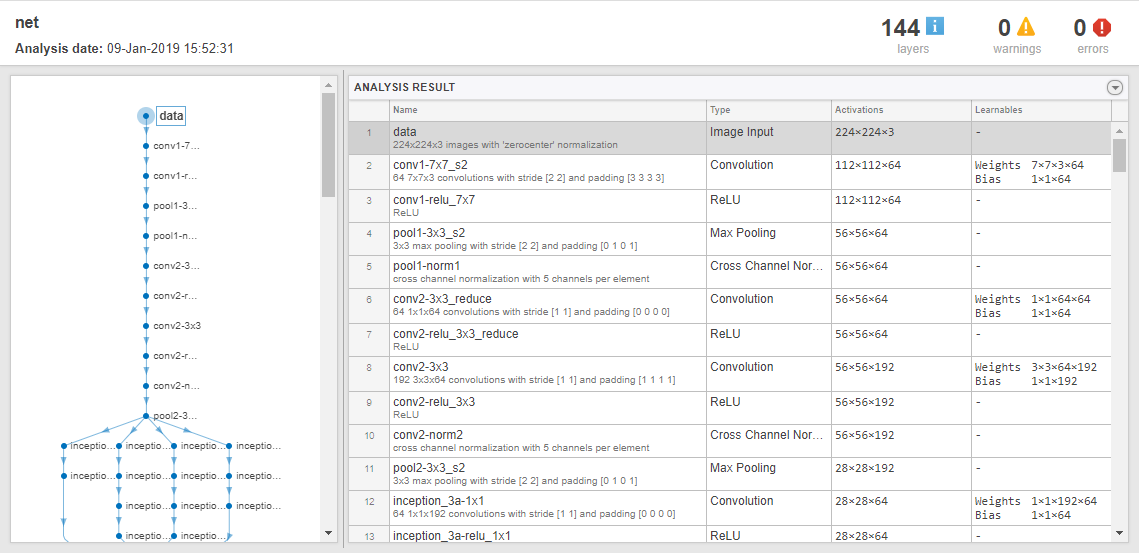

net.Layers(1);
inputSize = net.Layers(1).InputSize;

## Replace Final Layers

Extract the layer graph from the trained network. If the network is a `SeriesNetwork` object, such as AlexNet, VGG-16, or VGG-19, then convert the list of layers in `net.Layers` to a layer graph.

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

Find the names of the two layers to replace. You can do this manually or you can use the supporting function [findLayersToReplace](matlab:edit(fullfile(matlabroot,'examples','nnet','main','findLayersToReplace.m'))) to find these layers automatically. 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer];

In most networks, the last layer with learnable weights is a fully connected layer. Replace this fully connected layer with a new fully connected layer with the number of outputs equal to the number of classes in the new data set (5, in this example). In some networks, such as SqueezeNet, the last learnable layer is a 1-by-1 convolutional layer instead. In this case, replace the convolutional layer with a new convolutional layer with the number of filters equal to the number of classes. To learn faster in the new layer than in the transferred layers, increase the learning rate factors of the layer.

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

To check that the new layers are connected correctly, plot the new layer graph and zoom in on the last layers of the network.

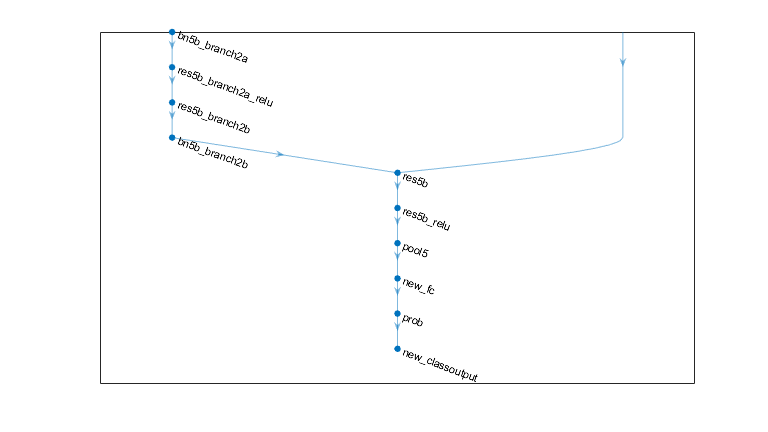

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph);
ylim([0,10]);

## Freeze Initial Layers

layers = lgraph.Layers;
connections = lgraph.Connections;

frozen = 17;
layers(1:frozen) = freezeWeights(layers(1:frozen));
lgraph = createLgraphUsingConnections(layers,connections);

## Train Network

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain, ...
    'DataAugmentation',imageAugmenter,"ColorPreprocessing","gray2rgb");

To automatically resize the validation images without performing further data augmentation, use an augmented image datastore without specifying any additional preprocessing operations.

augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation,"ColorPreprocessing","gray2rgb");
augimdsTest = augmentedImageDatastore(inputSize,imdsTest,"ColorPreprocessing","gray2rgb");

Specify the training options.

miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

## Train the network using the training data.

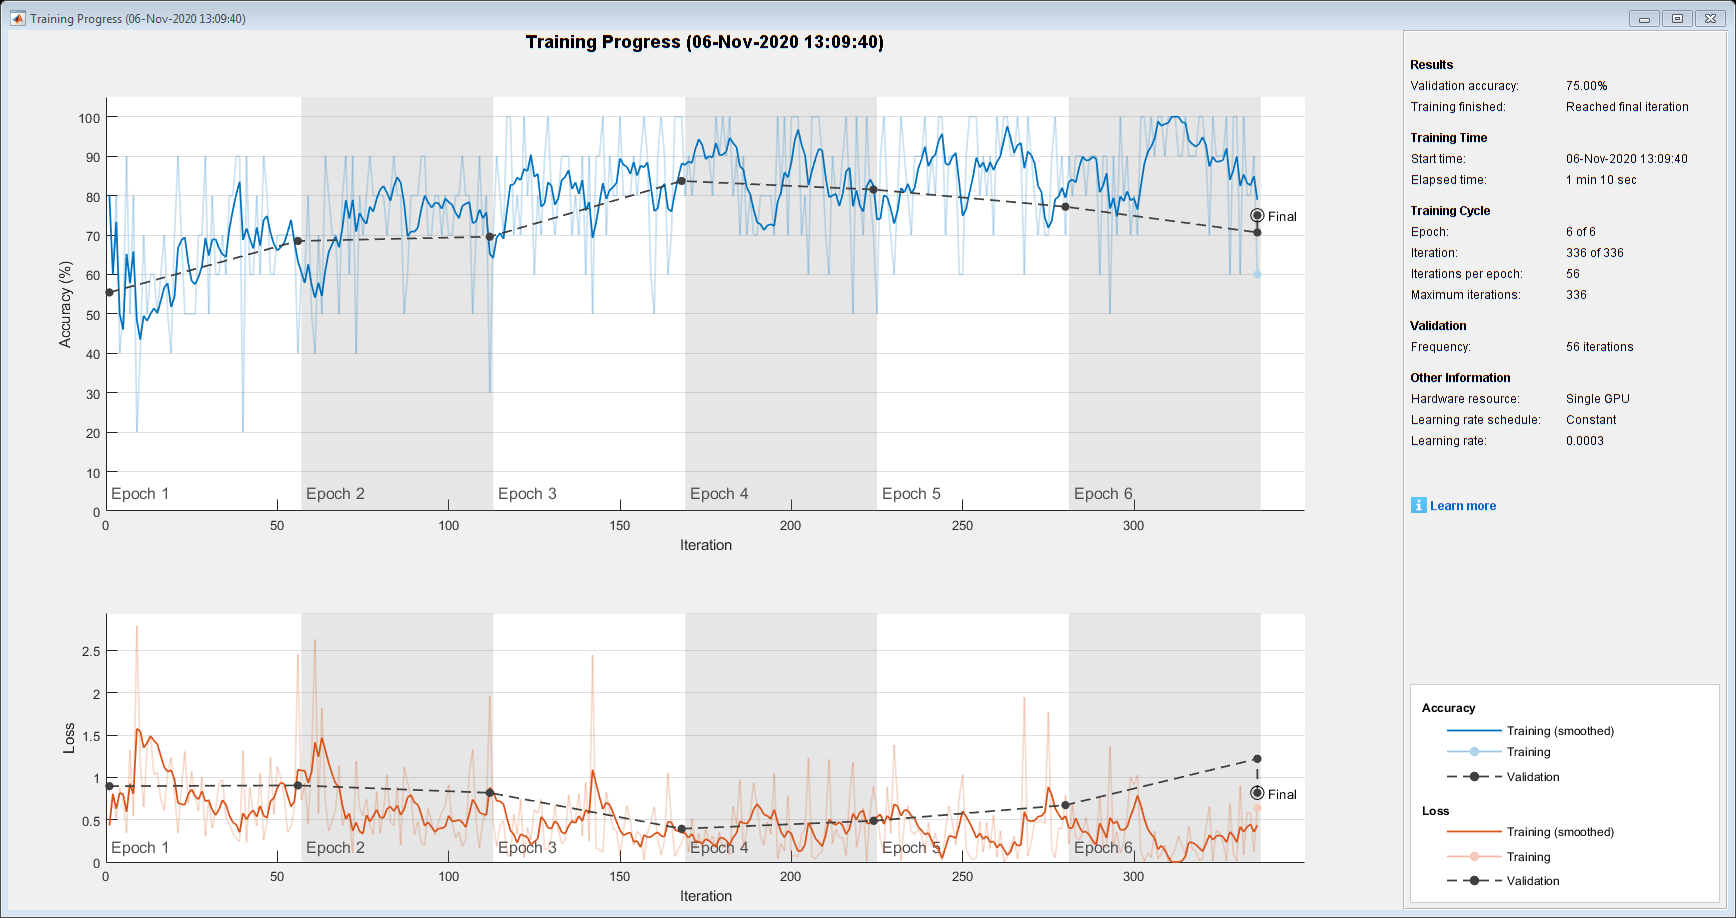

net = trainNetwork(augimdsTrain,lgraph,options);

## Classify Test Images

Classify the test images using the fine-tuned network, and calculate the test accuracy.

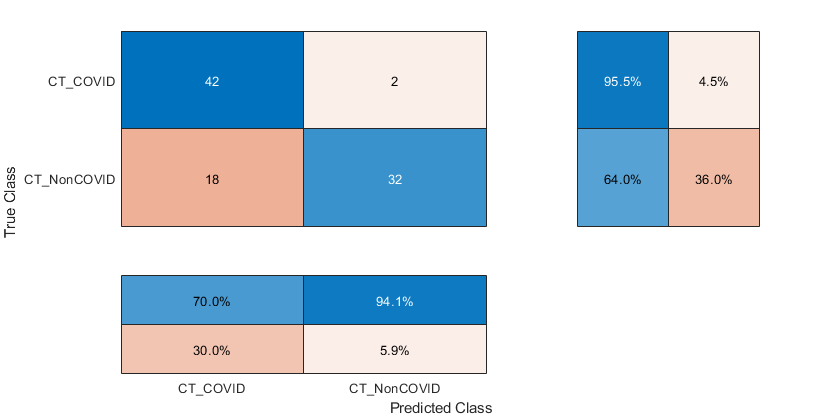

[YPred,probs] = classify(net,augimdsTest);

% Extract the class labels from the test data.
YTest = imdsTest.Labels;

accuracy = mean(YPred == YTest);

% Calculate Average F-score.
s = max(size(unique(YTest)));
conf_values = confusionmat(YTest, YPred);
tp_m = diag(conf_values); 
for i = 1:s
    % True positive are the diagonals.
    TP = tp_m(i);
    % False positives are everything (excluding the TP) in the COLUMN.
    FP = sum(conf_values(:, i), 1) - TP;
    % False Negatives are everything (excluding the TP) in the ROW.
    FN = sum(conf_values(i, :), 2) - TP;
    % True Negatives are everything else not in the same ROW **OR** COLUMN
    TN = sum(conf_values(:)) - TP - FP - FN;
    % Calculate Recall
    Recall = TP ./(TP + FN);
    if isnan(Recall)
        Recall = 0;
    end
    % Calculate Precision
    Precision = TP ./ (TP + FP);
    if isnan(Precision)
        Precision = 0;
    end
    % Calculate FScore
    FScore = (2*(Precision * Recall)) / (Precision+Recall);
    if isnan(FScore)
        FScore = 0;
    end
 
    fscore(i) = FScore;
end
avg_f_score = mean(fscore(:));

% Display confusion chart.
fig = figure;
conf = confusionchart(YTest, YPred,'RowSummary','row-normalized','ColumnSummary','column-normalized');
fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;

accuracy

accuracy = 0.7872

fscore

fscore =     0.8077    0.7619


avg_f_score

avg_f_score = 0.7848

Display four sample validation images with predicted labels and the predicted probabilities of the images having those labels.

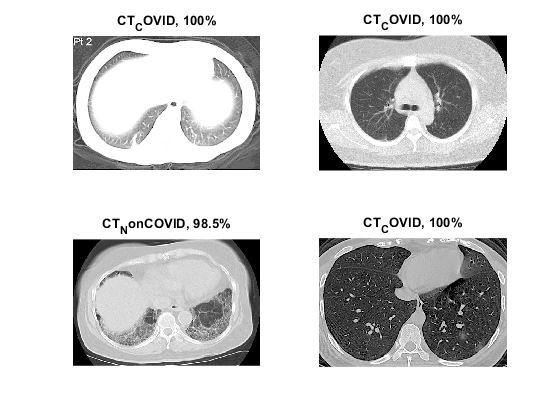

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end